% Bruno Sousa - 2019103045
% Raquel Mendes - 2012016451

clear

syms y(t)

f =@(t,y) t*(2.128-(0.0432*t))

f = function_handle with value:
    @(t,y)t*(2.128-(0.0432*t))


a = 0

a = 0

b = 5

b = 5


if(b<=a)
    error("O 'b' não pode ser menor ou igual a 'a'");
end

n = 10

n = 10


if(n<=0)
    error("O 'n' não pode ser menor ou igual a zero!");
end

y0 = 0.24

y0 = 0.2400

esc = 4

esc = 4

yEulerK4 =     0.2400    0.5042    1.2896    2.5854    4.3808    6.6650    9.4272   12.6566   16.3424   20.4738   25.0400


$$sExata = \frac{6}{25}-\frac{t^{2}\,\left(9\,t-665\right)}{625}$$

g = function_handle with value:
    @(t)eval(vectorize(char(sExata)))


tabela =          0    0.2400    0.2400         0
    0.5000    0.5042    0.5042         0
    1.0000    1.2896    1.2896         0
    1.5000    2.5854    2.5854         0
    2.0000    4.3808    4.3808         0
    2.5000    6.6650    6.6650         0
    3.0000    9.4272    9.4272    0.0000
    3.5000   12.6566   12.6566    0.0000
    4.0000   16.3424   16.3424         0
    4.5000   20.4738   20.4738         0


ans = 11×4 table
     t     Exata      NRK4      erroNRK4 
    ___    ______    ______    __________

      0      0.24      0.24             0
    0.5    0.5042    0.5042             0
      1    1.2896    1.2896             0
    1.5    2.5854    2.5854             0
      2    4.3808    4.3808             0
    2.5     6.665     6.665             0
      3    9.4272    9.4272    1.7764e-15
    3.5    12.657    12.657    1.7764e-15
      4    16.342    16.342             0
    4.5    20.474    20.474             0
      5     25.04     25.04             0


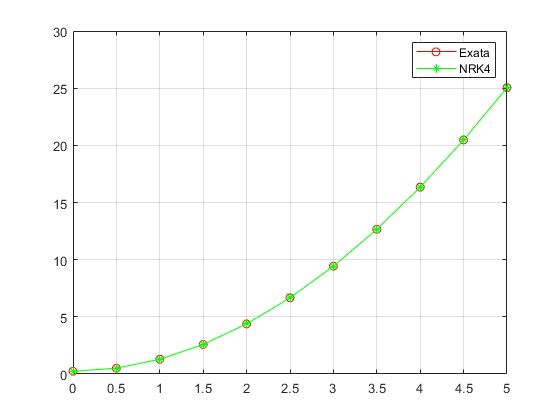

switch esc
    case 1              
        yEuler = NEuler(f,a,b,n,y0)
        
        sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0)
        fplot(sExata,[a,b])
        
        g =@(t) eval(vectorize(char(sExata)))
        
        h = (b-a)/n;
        t = a:h:b;
        yExata = g(t);
        erroEuler = abs(yExata-yEuler);
        tabela = [t.',yExata.',yEuler.',erroEuler.']
        array2table(tabela,"VariableNames",{'t','Exata','Euler','erroEuler'})
        
        plot(t,yExata,"-ro")
        hold on
        plot(t,yEuler,"-g*")
        hold off
        grid on
        legend('Exata','Euler')
        
    case 2
        
        yEulerM = NEulerM(f,a,b,n,y0)
        
        sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0)
        fplot(sExata,[a,b])
        
        g =@(t) eval(vectorize(char(sExata)))
        
        h = (b-a)/n;
        t = a:h:b;
        yExata = g(t);
        erroEuler = abs(yExata-yEulerM);
        tabela = [t.',yExata.',yEulerM.',erroEuler.']
        array2table(tabela,"VariableNames",{'t','Exata','EulerM','erroEulerM'})
        
        plot(t,yExata,"-ro")
        hold on
        plot(t,yEulerM,"-g*")
        hold off
        grid on
        legend('Exata','EulerM')
        
    case 3
        
        yEulerK2 = NRK2(f,a,b,n,y0)
        
        sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0)
        fplot(sExata,[a,b])
        
        g =@(t) eval(vectorize(char(sExata)))
        
        h = (b-a)/n;
        t = a:h:b;
        yExata = g(t);
        erroEuler = abs(yExata-yEulerK2);
        tabela = [t.',yExata.',yEulerK2.',erroEuler.']
        array2table(tabela,"VariableNames",{'t','Exata','NRK2','erroNRK2'})
        
        plot(t,yExata,"-ro")
        hold on
        plot(t,yEulerK2,"-g*")
        hold off
        grid on
        legend('Exata','NRK2')
        
    case 4
        
        yEulerK4 = NRK4(f,a,b,n,y0)
        
        sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0)
        fplot(sExata,[a,b])
        
        g =@(t) eval(vectorize(char(sExata)))
        
        h = (b-a)/n;
        t = a:h:b;
        yExata = g(t);
        erroEuler = abs(yExata-yEulerK4);
        tabela = [t.',yExata.',yEulerK4.',erroEuler.']
        array2table(tabela,"VariableNames",{'t','Exata','NRK4','erroNRK4'})
        
        plot(t,yExata,"-ro")
        hold on
        plot(t,yEulerK4,"-g*")
        hold off
        grid on
        legend('Exata','NRK4')
        
    case 5
        
        tspan = [a b];
        [odeT,odeY] = ode45(f,tspan,y0);
        
        sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0)
        fplot(sExata,[a,b])
        
        g =@(t) eval(vectorize(char(sExata)))
        
        h = (b-a)/n;
        t = a:h:b;
        yExata = g(t);
        
        plot(t,yExata,"-bo")
        hold on
        plot(odeT,odeY,"-ro")
        grid on
        legend('Exata','ODE')
        hold off
        grid on
        array2table([odeT,odeY],"VariableNames",{'t','y'})
end

%whos

 
